clc
clear
close all
load("sim_ntl.mat")

### VEHICLE

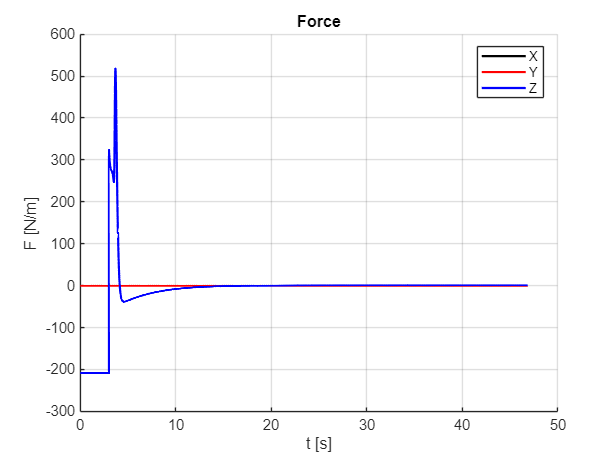

plotVariable(out.main_clock, out.F_total, "t [s]", "F [N/m]", "Force")

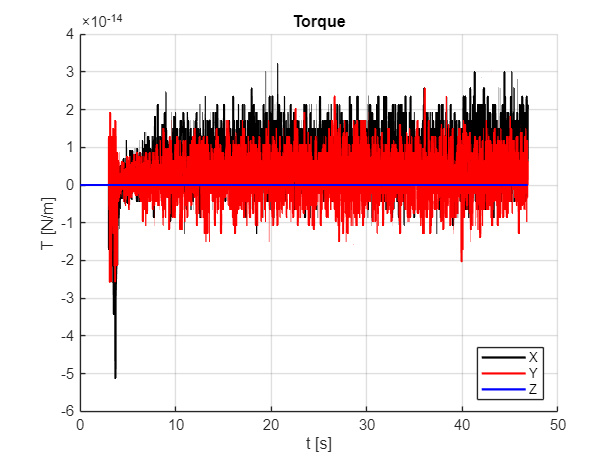


plotVariable(out.main_clock, out.T_total, "t [s]", "T [N/m]", "Torque")

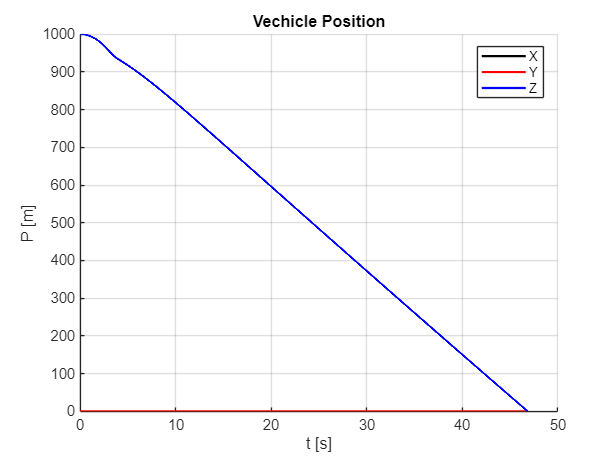

plotVariable(out.main_clock, out.vehicle_position, "t [s]", "P [m]", "Vechicle Position")

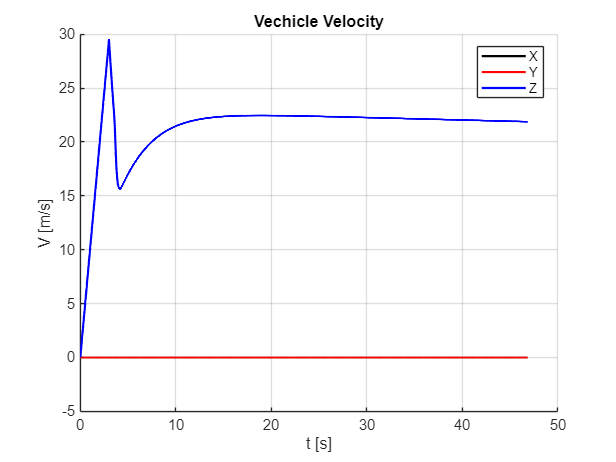

plotVariable(out.main_clock, -out.vehicle_velocity, "t [s]", "V [m/s]", "Vechicle Velocity")

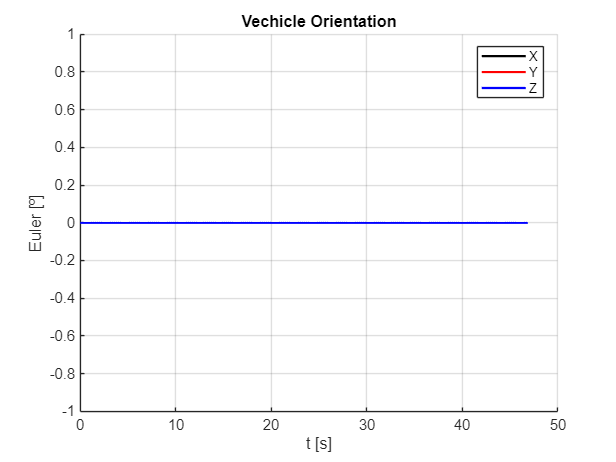

plotVariable(out.main_clock, out.vehicle_orientation, "t [s]", "Euler [º]", "Vechicle Orientation")

### ROTOR

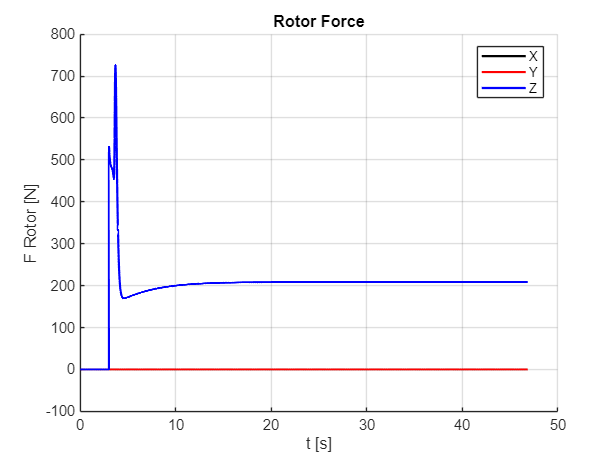

plotVariable(out.main_clock, out.F_rotor, "t [s]", "F Rotor [N]", "Rotor Force")

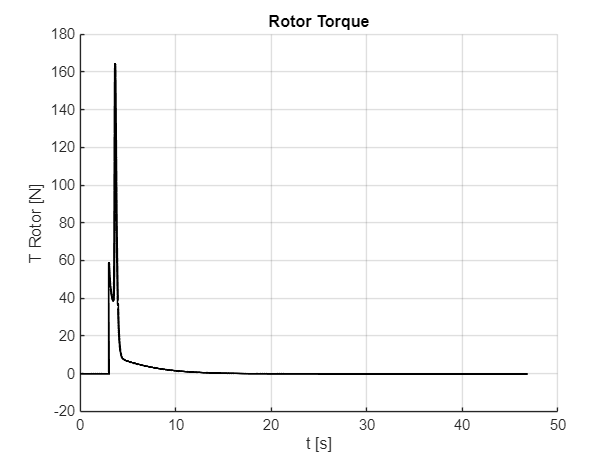

plotVariable(out.main_clock, out.T_rotor, "t [s]", "T Rotor [N]", "Rotor Torque")

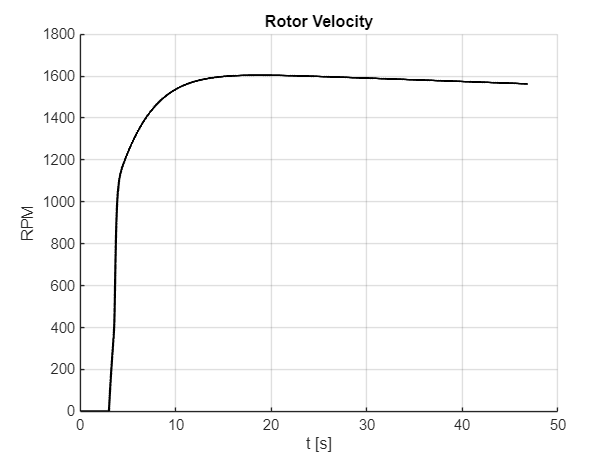

plotVariable(out.main_clock, out.rotor_rpm, "t [s]", "RPM", "Rotor Velocity")

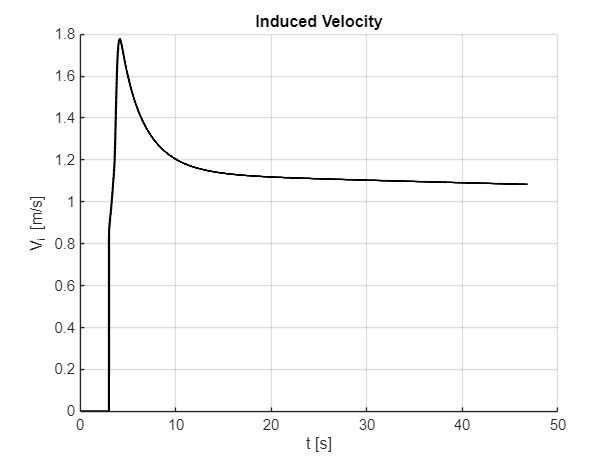

plotVariable(out.main_clock, out.rotor_induced_velocity, "t [s]", "V_i [m/s]", "Induced Velocity")

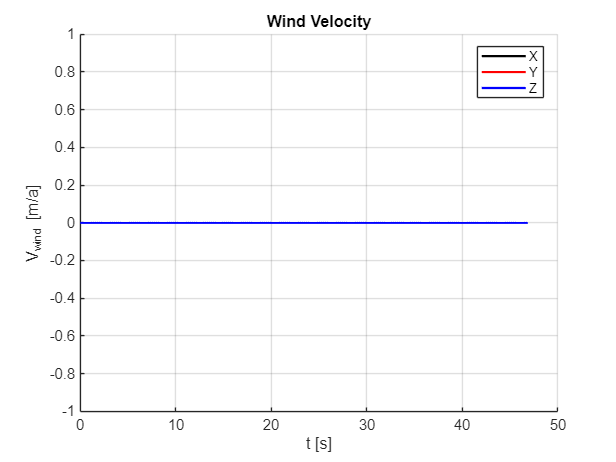


plotVariable(out.main_clock, out.wind_velocity, "t [s]", "V_{wind} [m/a]", "Wind Velocity")

### BLADE DISTRIBUTION ANALYSIS

t = 2;
azimute = 0;
[~, i] = min(abs(out.rotor_data.time - t))

i = 1

out.rotor_data.time(i)

ans = 3.0100

data_rotor = out.rotor_data.data(i)

data_rotor =   RotorAzimutalDistribution with properties:

    blade_distribution_data: [1×10 BladeDistribution]
          azimutal_position: [10×1 double]


[~, i] = min(abs(data_rotor.azimutal_position - azimute));
data_blade = data_rotor.blade_distribution_data(i);
xx = linspace(0, 1, length(data_blade.total_velocity))

xx =          0    0.0133    0.0267    0.0400    0.0533    0.0667    0.0800    0.0933    0.1067    0.1200    0.1333    0.1467    0.1600    0.1733    0.1867    0.2000    0.2133    0.2267    0.2400    0.2533    0.2667    0.2800    0.2933    0.3067    0.3200    0.3333    0.3467    0.3600    0.3733    0.3867    0.4000    0.4133    0.4267    0.4400    0.4533    0.4667    0.4800    0.4933    0.5067    0.5200    0.5333    0.5467    0.5600    0.5733    0.5867    0.6000    0.6133    0.6267    0.6400    0.6533


azimutes = data_rotor.azimutal_position;

#### Velocity

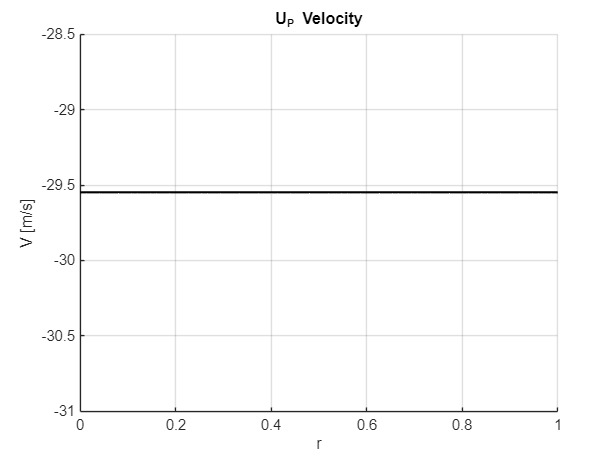

plotVariable(xx, data_blade.U_P, "r", "V [m/s]", "U_P Velocity")

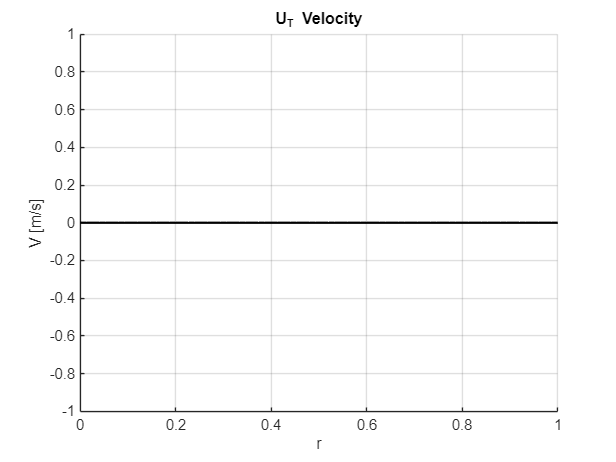

plotVariable(xx, data_blade.U_T, "r", "V [m/s]", "U_T Velocity")

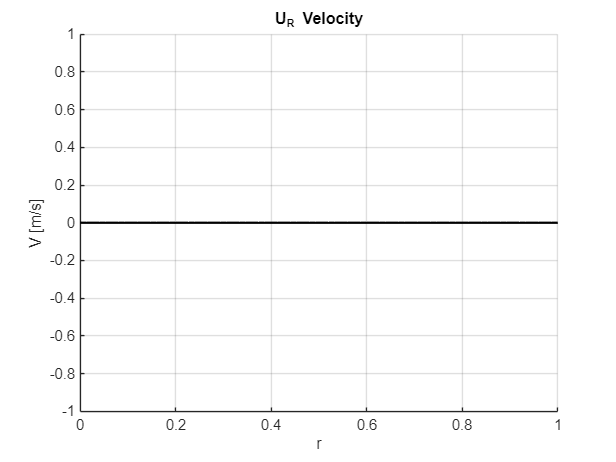

plotVariable(xx, data_blade.U_R, "r", "V [m/s]", "U_R Velocity")

#### Angles

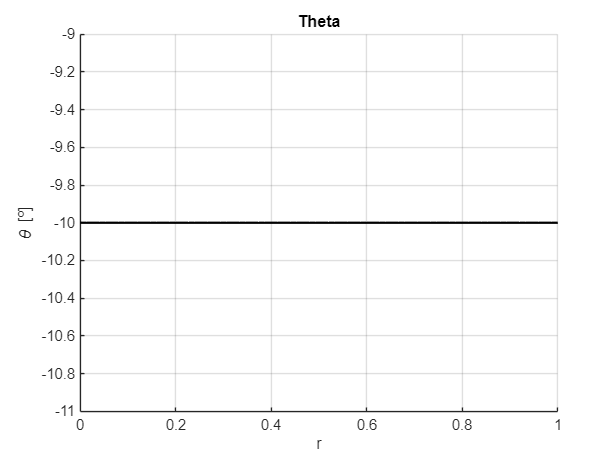

plotVariable(xx, data_blade.theta, "r", "\theta [º]", "Theta")

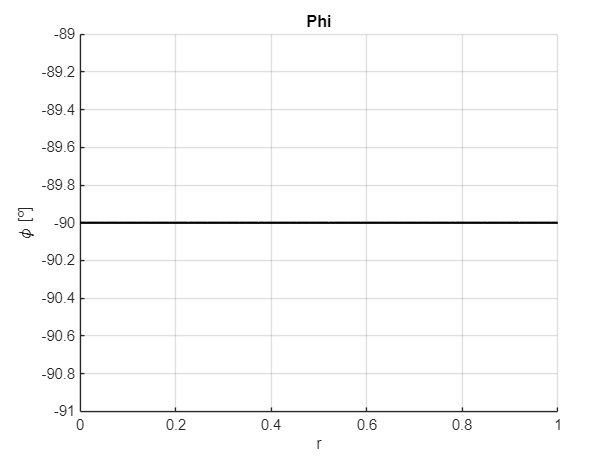

plotVariable(xx, data_blade.phi, "r", "\phi [º]", "Phi")

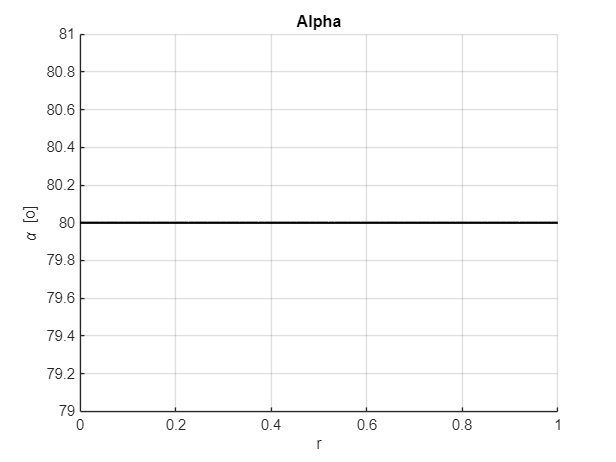

plotVariable(xx, data_blade.alpha, "r", "\alpha [o]", "Alpha")

#### Reynolds Number

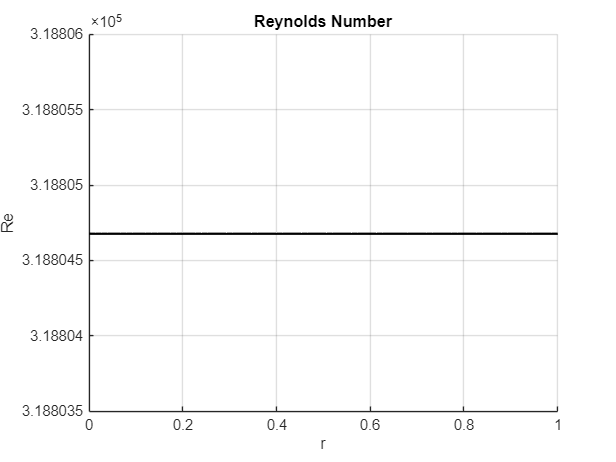

plotVariable(xx, data_blade.Re, "r", "Re", "Reynolds Number")

#### Aerodynamic Coefficients

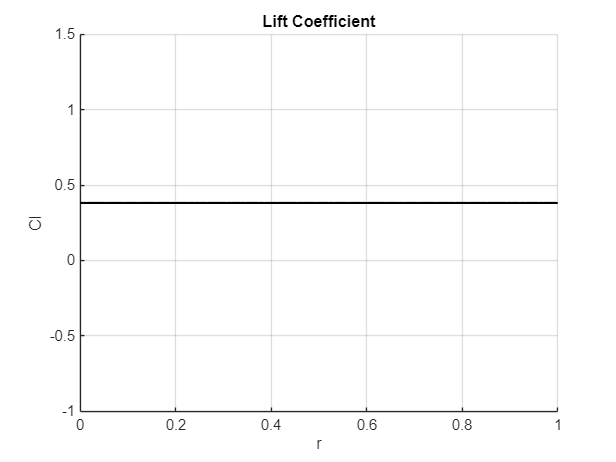

plotVariable(xx, data_blade.Cl, "r", "Cl", "Lift Coefficient")

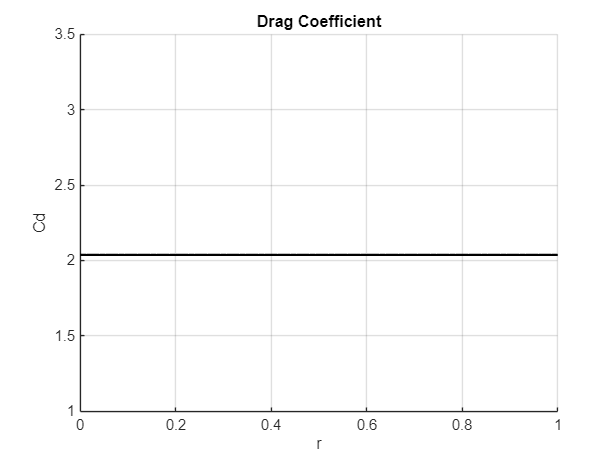

plotVariable(xx, data_blade.Cd, "r", "Cd", "Drag Coefficient")

#### Forces in Aerodynamic Frame

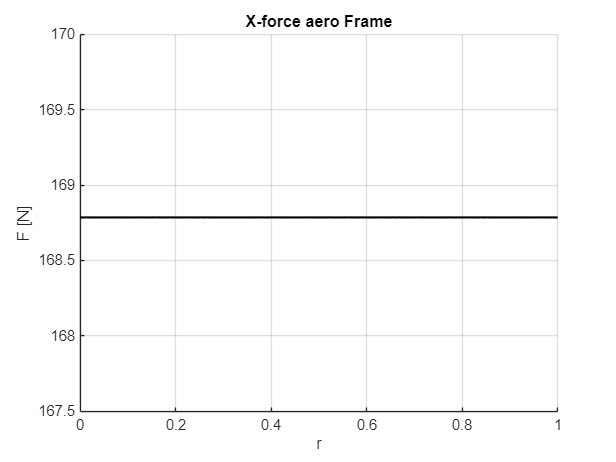

plotVariable(xx, data_blade.dF_a_x, "r", "F [N]", "X-force aero Frame")

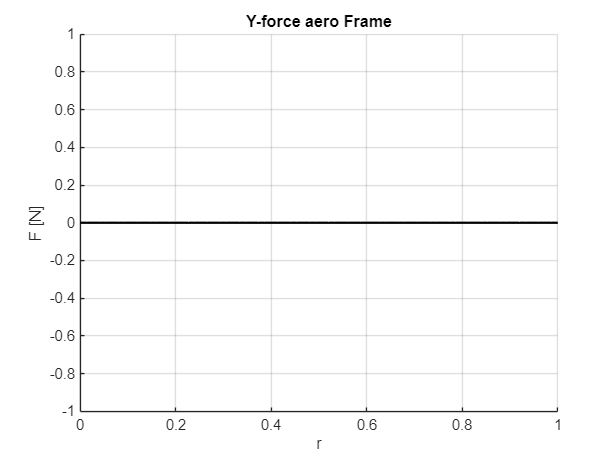

plotVariable(xx, data_blade.dF_a_y, "r", "F [N]", "Y-force aero Frame")

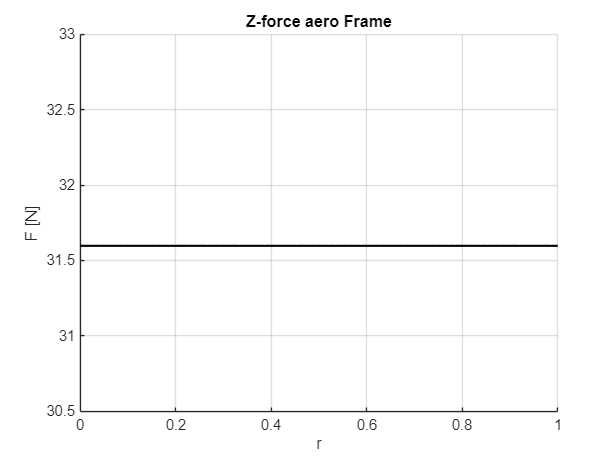

plotVariable(xx, data_blade.dF_a_z, "r", "F [N]", "Z-force aero Frame")

#### Forces in Element Frame

Aqui o sinal (-) significa que a contribuição da força aerodinâmica gera uma força que cria rotação

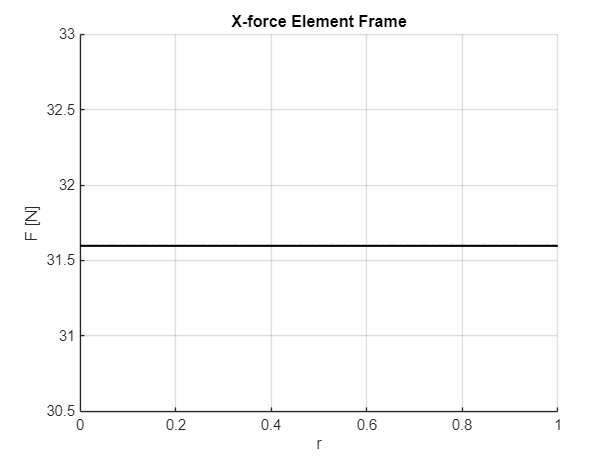

plotVariable(xx, -data_blade.dF_e_x, "r", "F [N]", "X-force Element Frame")

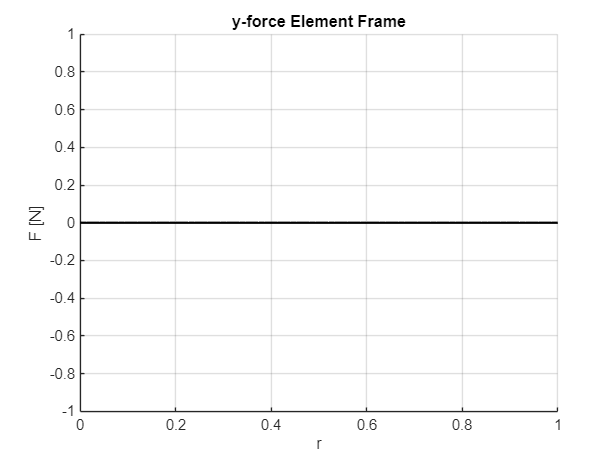

plotVariable(xx, data_blade.dF_e_y, "r", "F [N]", "y-force Element Frame")

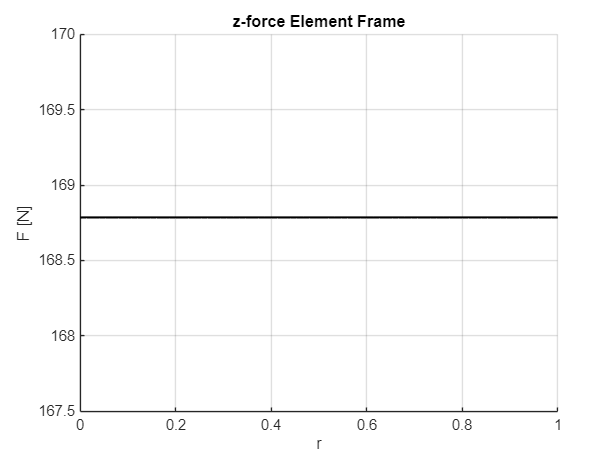

plotVariable(xx, data_blade.dF_e_z, "r", "F [N]", "z-force Element Frame")

#### Prandtl Function

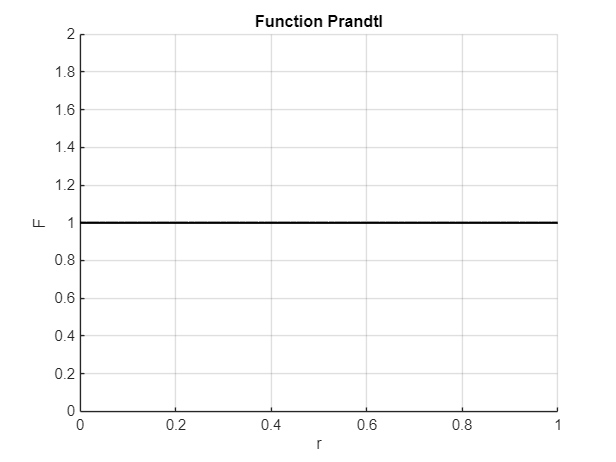

plotVariable(xx, data_blade.f_prandtl, "r", "F", "Function Prandtl")

### ROTOR DISTRIBUTION ANALYSIS

#### Forces

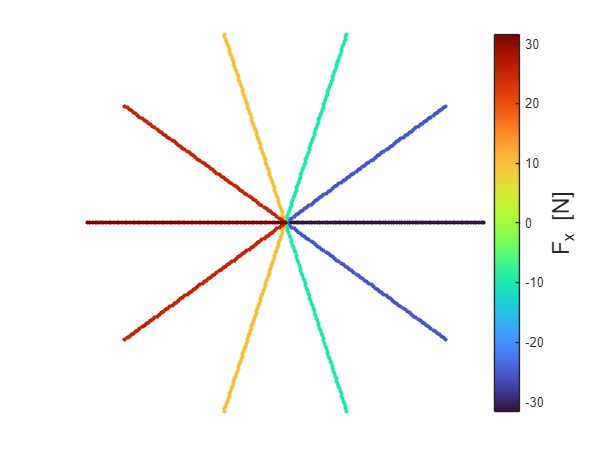

for i=1:length(azimutes)
    valores(i, :) = data_rotor.blade_distribution_data(i).dF_i_x;
end
polarPlot(azimutes, xx, valores, "", "F_x [N]", "")

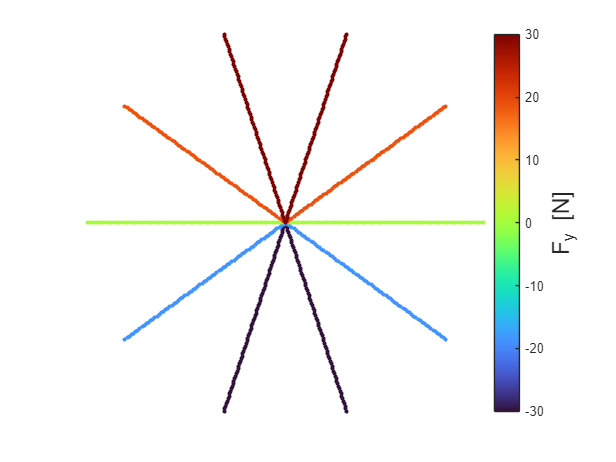

for i=1:length(azimutes)
    valores(i, :) = data_rotor.blade_distribution_data(i).dF_i_y;
end
polarPlot(azimutes, xx, valores, "", "F_y [N]", "")

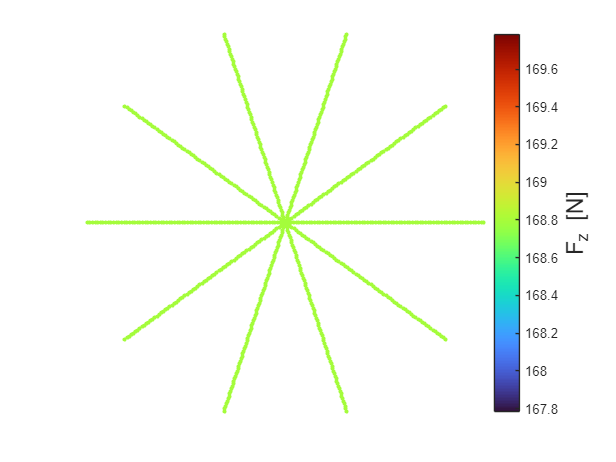

for i=1:length(azimutes)
    valores(i, :) = data_rotor.blade_distribution_data(i).dF_i_z;
end
polarPlot(azimutes, xx, valores, "", "F_z [N]", "")